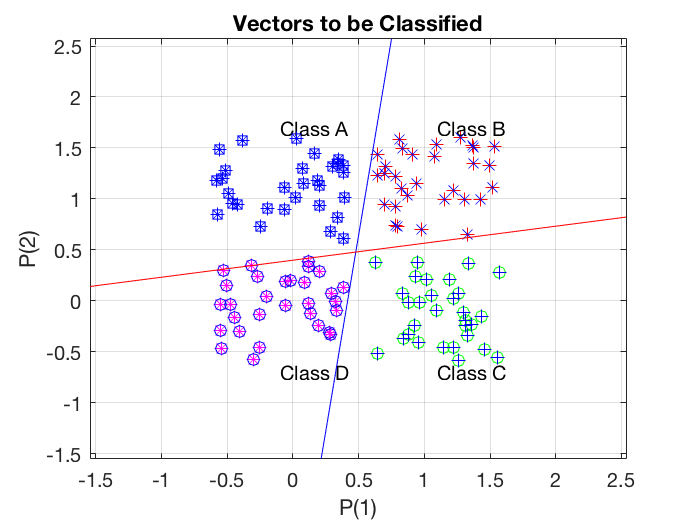

% >>>>>. Task 5 
close all, clear all  clc
% number of samples of each class
K = 30;
% define classes
q = .6; % offset of classes
A = [rand(1,K)-q; rand(1,K)+q]; 
B = [rand(1,K)+q; rand(1,K)+q]; 
C = [rand(1,K)+q; rand(1,K)-q];
D = [rand(1,K)-q; rand(1,K)-q];
% plot classes
plot(A(1,:),A(2,:),'bs')
hold on
grid on
plot(B(1,:),B(2,:),'r+')
plot(C(1,:),C(2,:),'go')
plot(D(1,:),D(2,:),'m*')
% text labels for classes
text(.5-q,.5+2*q,'Class A')
text(.5+q,.5+2*q,'Class B')
text(.5+q,.5-2*q,'Class C')
text(.5-q,.5-2*q,'Class D')
% define output coding for classes. This coding is used for visualizations purposes.
a = [0 1]';
b = [1 1]';
c = [1 0]';
d = [0 0]';

% define inputs (combine samples from all four classes)
P = [A B C D];
% define targets
T = [repmat(a,1,length(A)) repmat(b,1,length(B)) repmat(c,1,length(C)) repmat(d,1,length(D))];
 % repmat: Replicate and tile an array 
plotpv(P,T);

% create the perceptron 
net = perceptron;
% To see the adaptation you need to look at the plot while the code is running
E = 1;
net.adaptParam.passes = 1;
linehandle = plotpc(net.IW{1},net.b{1});
n = 0;
while (sse(E) && n<1000)
% sse: Sum squared error or mae: mean absolute error
    n = n+1;
    [net,Y,E] = adapt(net,P,T);
    linehandle = plotpc(net.IW{1},net.b{1},linehandle);
    drawnow;
    pause(2); % 2 seconds pause
end

% show perceptron structure
view(net);

% For example, classify an input vector of [0.7; 1.2]
p = [0.7; 1.2]

p =     0.7000
    1.2000


y = net(p)

y =      1
     1


% compare response with output coding (a,b,c,d)
